# 802.11 OFDM Demodulation and Equalization

This lab will build on the previous lab to perform the OFDM demodulation and equalization.  In doing this lab, you will learn to:

- Compute the parameters of an OFDM system

- Extract the payload and data components in an 802.11g packet

- Perform the OFDM demodulation of the components

- Build a simple channel estimator

- Equalize the symbols with estimated channel

- Visualize the equalized symbols

**Files**:  The lab requires a set of files to complete.   The files are:

- `wlanEqualization.mlx`:  This file, which is the main file.

- `WLANPktAnalyzer.m`:  Class for analyzing the OFDM structure of the     transmitted data

- `WLANRx.m`:  Main RX class that performs the OFDM channel estimation and equalization

- `RandMPChan.m`: Class for creating a random multi-path channel

In addition, we will use several completed versions of files from the previous lab.  If you have completed these labs, you can use the solution you wrote.  NYU students in the class will also be provided the files in Brightspace.

- WLANTx.m:  Transmitter class. 

- `TxFilt.m, RxFil.m`:  Classes for up and down-converting signals

- `WLANDetect.m`:  Class for detecting the packet

**Submission**:  Complete all the TODO sections of the files.  Run the main wlanEqualization.mlx file.  Print to PDF and submit the PDF.

## 802.11g OFDM Packet Structure

The 802.11g WLAN standard has a simple packet structure that is excellent starting point to building a simple communication system.  The basic packet format is shown below.  

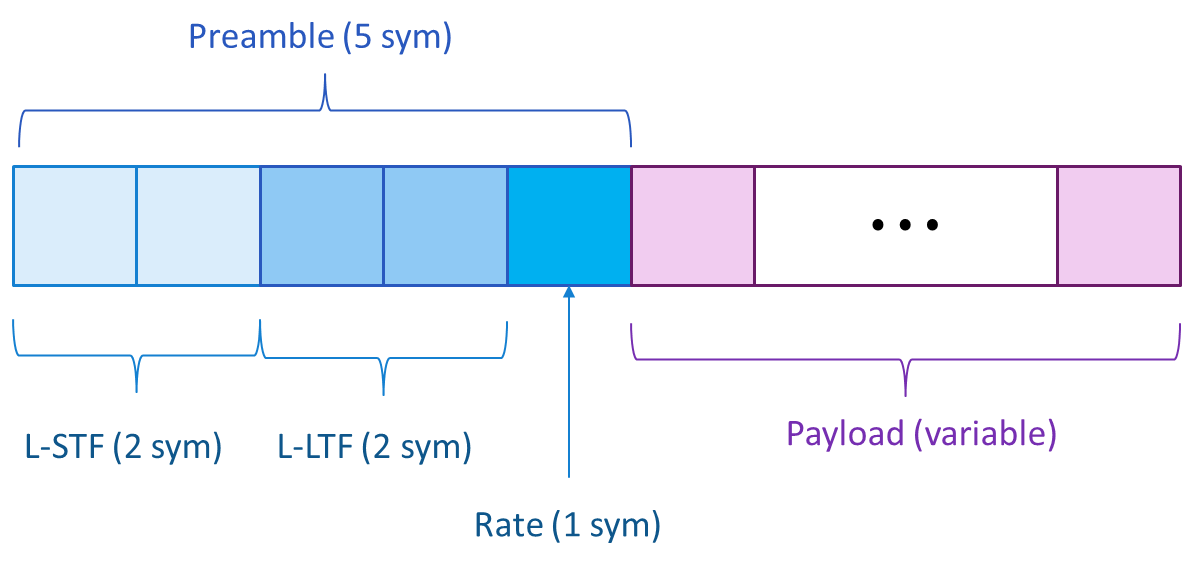

The packet has two parts:  a **preamble** and **payload**.  In the 802.11g standard, the preamble has 5 OFDM symbols divided into three parts:

- Legacy STF (2 OFDM symbols) for the AGC and packet detection.  We used this field in the previous lab

- Legacy LTF (2 OFDM symbols).  In the previous lab, we used this for fine timing estimation.  Here, we will use also use this for channel estimation.

- Rate (1 OFDM symbol).  This field signals the MCS and length of the payload.  We will ignore this field in this lab.

All the preamble fields are encoded in an offset QPSK.  Once the rate field is decoded, the payload can be decoded.  The payload length varies depending on the number of bits to be transmitted and the MCS.

Each OFDM symbol has parameters 

- FFTLength = 64, which is also equal to the number of sub-carriers

- CPLength = 16

Within the 64 sub-carriers, the WLAN signal is sent on 62 so-called active sub-carriers as shown in this  figure from the [OpenOFDM](https://openofdm.readthedocs.io/en/latest/eq.html) documentation:

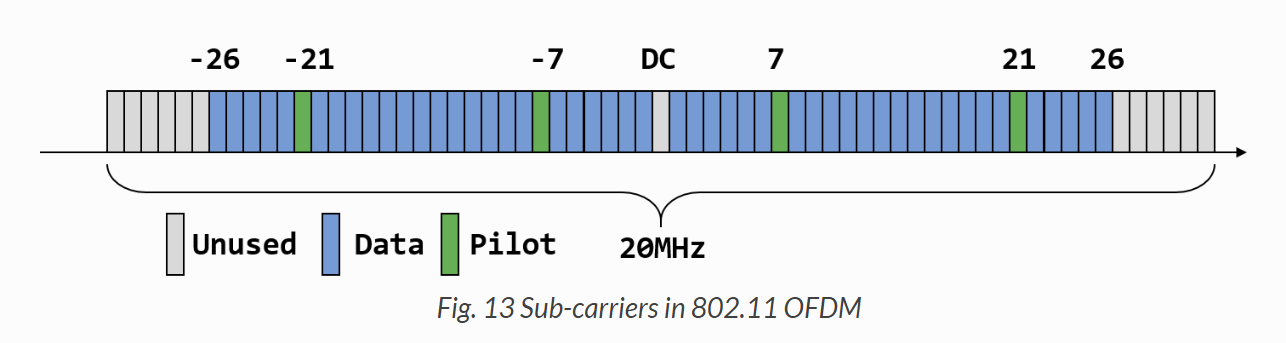

There are 52 used sub-carriers and 12 unused sub-carriers. The DC is one of the un-used sub-carriers since it is contains LO leakage.  In the payload symbols, four of the sub-carriers are reserved for pilots and the remaining 48 are reserved for data.

## Visualizing an OFDM Packet

We can create the packet with the `WLANTx` class as follows.  This class has already been written and you do not need to modify it.  We select MCS=5 for 16-QAM but you can use any MCS from 0 to 7

mcs = 4;  
psduLen = 512;
wlantx = WLANTx('psduLen', psduLen, 'mcs', mcs);
x = wlantx();

To analyze the packet, we will create a packet analyzer class, `WLANPktAnalyzer`.  Complete the constructor and the `extractLTFSym` method in the class to obtain:

- `sym`:  The OFDM modulation symbols in the preamble and payload.  This should be a 52 x n array where n is the total number of symbols.

- `symLTF`:  The OFDM modulation symbols in the LTF field.  This should be a 52 x 2 array since the LTF field is 2 OFDM symbols

Once you have completed this code, run the following command to extract the symbols and plot the constellation for the LTF modulation symbols.  You should see that the LTF symbols are QPSK, but aligned on the I-Q axis:

% TODO:  Compltee WLANPktAnalyzer constructor and extractSym method, then
% run the following.
pktAnal = WLANPktAnalyzer();
pktAnal.extractLTFSym(x);

% TODO:  Plot the constellation in pktAnal.symLTF.

Next, complete the method in `WLANPktAnalyzer.extractPayloadSym `that will extract the OFDM modulation symbols for the data and pilots in the payload portion of the packet.   This will create two arrays:

- `symPilot:  4 x nsymPayload` array of pilots in the `nsymPayload` symbols of the payload.  These should be BPSK

- `symData:  48 x nsymPayload` array of pilots in the `nsymPayload` symbols of the payload.  If you selected MCS=5, they will be 16-QAM

After completing the code, plot the TX constellation points for the symbols and pilots.  

% TODO:  Complete the code in WLANPktAnalyzer.extractPayloadSym.  Then, run
% the following code
pktAnal = WLANPktAnalyzer();
pktAnal(x);


% TODO:  Plot the pilot and data constellation points that should be stored
% in pktAnal.symPilot and pktAnal.symData


The 802.11g standard has 8 MCS values as given by the following table.  

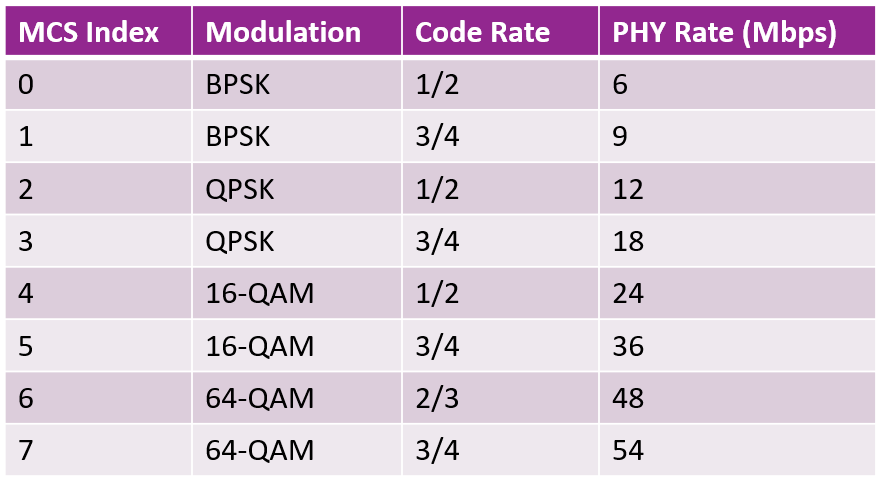

In this lab, we have hard-coded the MCS with the `mcs` index above.   We use the MCS, to compute the bits per symbol.

if mcs<= 1
    bitsPerSym = 1;      % BPSK
elseif mcs<=3
    bitsPerSym = 2;      % QPSK
elseif mcs<=5
    bitsPerSym = 4;      % 16-QAM
else
    bitsPerSym = 6;      % 64-QAM
end


Based on the size of the array `pktAnal.symData` compute and print

- `nscData`:  Number of sub-carriers per OFDM symbol for data

- `nsymData`:  Number of OFDM symbols for the data

- `nREData = nsymData*nscData`:  Total number of modulation symbols or resource elements (REs) for the data 

- `ncodedBits`:  Total number of coded data bits (use the bitsPerSym above)

- `codeRate`:  Use the psduLen and ncodeBits.  This may be a little < the code rate in the table since there is some zero padding.

% TODO:  Compute and print the above values




## Creating a Synthetic Multi-Path Channel

To simulate the WLAN transmission, I have provided a function, `RandMPChan, `that creates a random multipath channel.  This class is complete, and you do not need to modify it.  We can create the channel as follows.  Similar to the previous lab, the channel runs at an upsampled rate, `fsampUp`.

%  Compute the upsampled data rate
ovRatio = 2;
fsampUp = fsamp*ovRatio;

% Create the channel
chan = RandMPChan("fsamp", fsampUp);

% Generate random multi-paths
chan.genPath();

After generating the multipath, the path components are stored in arrays:

- `chan.dly(i)`:  Delay of multi-path component `i` in seconds

- `chan.gain(i)`:  Gain of multi-path component `i` in dB

Compute the excess delay of each path:  `t(i) = chan.dly(i)-min(chan.dly)` which represents the additional delay relative to the first path.  Plot `chan.gain(i)` vs. t(i) in nano-seconds using a stem plot to visualize the paths.  You may wish to set the `BaseValue` parameter of the `stem` function to some value to visualize the paths well

% TODO:  
%  t = ...
%  stem(...)


We can now create all the objects we need for TX and RX the packet.

% Create the TX and packet analyzer
wlantx = WLANTx('psduLen', psduLen, 'mcs', mcs);
pktAnal = WLANPktAnalyzer();

% Compute the signal parameters
info = wlanNonHTOFDMInfo('NonHT-Data');
fsamp = wlantx.fsamp;
sigBW = (max(info.ActiveFFTIndices)-min(info.ActiveFFTIndices)+1)/info.FFTLength*fsamp;

% Create the upsampling and downsampling filters
ovRatio = 2;
fsampUp = fsamp*ovRatio;
txFilt = TxFilt('ovRatio', ovRatio, 'rateIn', fsamp, 'sigBW', sigBW);
rxFilt = RxFilt('ovRatio', ovRatio, 'rateIn', fsampUp, 'sigBW', sigBW);

% Create the packet detector 
wlanDet = WLANDetect();

We now run the data through the objects as follows.

% Create a RX signal
snr = 10;

% Generate the TX packet, analyze and up-sample
x = wlantx();
pktAnal(x);
xup = txFilt(x);

% Get the noise variance to match the SNR
Ex = mean(abs(xup).^2);
wvar = db2pow(-snr)*Ex;
chan.wvar = wvar;

% Pass data through channel
rup = chan(xup);

% Downsample
r = rxFilt(rup);

% Perform the STF and LTF detection
[pktFound, indltf] = wlanDet(r);

## Creating a Channel Estimate

We are now prepared to start creating the OFDM receiver.  We will use the WLANRx that can be created as follows.  The set `setPktData` method is used to pass the RX known data including the symbol values in the LTF and the number of symbols of the payload data.  The number of symbols of the payload data would normallly be read from the rate field, but we have hard-coded it here to make it easier.

wlanrx = WLANRx();
wlanrx.setPktData("symLTFTx", pktAnal.symLTF, 'nsymData', nsymData);

Complete the code in the method `WLANRx.compChanEstRaw` to:

- Extract the LTF field using the deteced start of the LTF field from the detector.

- Perform OFDM demodulation on the LTF field to the get the received LTF symbols` symLTFRx`

- Compute the raw channel estimate ``chanEst = symLTFRx ./ symLTFTx`


% TODO complete the code in WLANRx.compChanEstRaw.  Then, run the following
% code
wlanrx = WLANRx();
wlanrx.setPktData("symLTFTx", pktAnal.symLTF, 'nsymData', nsymData);
wlanrx.compChanEstRaw(r, indltf);


Once you have run the above code, `wlanrx.chanEstRaw` should be a 52 x 2 array corresponding to the channel estimates on the two symbols of the LTF field.  Plot the real components of these two channel estimates.

% TODO


We next smooth the channel estimate.  Complete the code in WLANRx.compChanEst.   Then run the following code.

% TODO complete the code in WLANRx.compChanEst.  Then, run the following
% code to compute the 
wlanrx = WLANRx();
wlanrx.setPktData("symLTFTx", pktAnal.symLTF, 'nsymData', nsymData);
wlanrx.compChanEst(r, indltf);

% TODO:  Plot the real component of the raw channel estimate on both symbols with `o` marker. 
% On the same plot, plot the real component of the smoothed channel
% estimate




## Bulding the Equalizer

We now build the equalizer.  Complete the code in the `WLANRx.symEq` method that:

- Finds the time-domain samples for the payload

- Performs the OFDM demodulation to extract an array raw symbols `sym`

- Equalize the symbols with the channel estimate

Two equalization methods are supported

- `inversion:  symEq(i,j) = sym(i,j) / obj.chanEst(i)`

- `MMSE:  symEq(i,j) = conj(chanEst(i))*sym(i,j) / (abs(chanEst(i)).^2 + noiseEst)`

The inversion method is simpler, but creates symbols with very high noise when the channel estimate is small.  The MMSE method provides lower overall error, but relies on the noise estimate.

% TODO:  Complete the code in WLANRx.eqSym, then run the following code
% which will perform the equalization
eqMethod = 'inversion';  % Set to either 'inversion' or 'MMSE'
wlanrx = WLANRx('eqMethod', eqMethod);
wlanrx.setPktData("symLTFTx", pktAnal.symLTF, 'nsymData', nsymData);
wlanrx(r, indltf);

% TODO:  The equalized data symbols are stored in wlanrx.symDataEq.
% Plot the equalized constellation points on the complex plane.


## Running the System over the Air

We will now run the symbol demodulation over the air.    We first set the parameters:

% TODO:  Set parameters
% Set to true for loopback, else set to false
loopback = true;  

% Select to run TX and RX
runTx = true;
runRx = true;

Create all the TX and RX objects.

% Create the TX and packet analyzer
psduLen = 512;
mcs = 4;
wlantx = WLANTx('psduLen', psduLen, 'mcs', mcs);
pktAnal = WLANPktAnalyzer();

% Compute the signal parameters
info = wlanNonHTOFDMInfo('NonHT-Data');
fsamp = wlantx.fsamp;
sigBW = (max(info.ActiveFFTIndices)-min(info.ActiveFFTIndices)+1)/info.FFTLength*fsamp;

% Create the upsampling and downsampling filters
ovRatio = 2;
fsampUp = fsamp*ovRatio;
txFilt = TxFilt('ovRatio', ovRatio, 'rateIn', fsamp, 'sigBW', sigBW);
rxFilt = RxFilt('ovRatio', ovRatio, 'rateIn', fsampUp, 'sigBW', sigBW);

% Create the packet detector 
wlanDet = WLANDetect();


Create a TX data

% TODO:  Generate the TX packet, analyze and up-sample 
%   x = wlantx();
%   pktAnal(...);


% TODO:  Get the number of symbols of data from the 
% size of pktAnal.symData;


% Set the packet size for the detector to ensure that it detects 
wlanDet.pktLen = length(x);


% TODO:  Create the up-sampled TX data
%   xup = ...

Create the TX and RX SDR objects

% clear previous instances
clear sdrtx sdrrx

% add path to the common directory where the function is found
addpath('..\..\common');

% Run the creation function.  
nsampsFrame = length(xup);
[sdrtx, sdrrx] = plutoCreateTxRx(createTx = runTx, createRx = runRx, loopback = loopback, ...
    nsampsFrame = nsampsFrame, sampleRate = fsampUp);


Next, we set the TX to continuously transmit the packet



if runTx
    % TODO:  Use the sdrtx.release() and sdrtx.transmitRepeat() commands to
    % continuously send xup
end

We will try to demodulate one packet

% TODO:  Capture data at the upsampled rate.  Capture 2*nsampsFrame since
% we want to make sure that we capture a full packet
%   rup = rx.capture(...)


% TODO:  Scale to floating point
%   rup = ...


% TODO:  Down-sample
%   r = rxFilt(...);


% TODO:  Run detection with the wlanDet class
%   [pktFound, indltf] = ...;


% Create the RX and set the packet info
eqMethod = 'inversion';  % Set to either 'inversion' or 'MMSE'
wlanrx = WLANRx('eqMethod', eqMethod);
wlanrx.setPktData("symLTFTx", pktAnal.symLTF, 'nsymData', nsymData);

% TODO:  Run the receiver
%   wlanrx(...)



% TODO: Plot the equalized constellation points on the complex plane.


## Running a Continuous Monitor

Complete the code below to run the code in a continuous monitor.  

% Number of iterations
nit = 100;

% Initialize arrays to store data
snrEst = zeros(nit,1);                  
rxTime = zeros(nit,1);

% Initialize plots
clf;
subplot(1,2,1);
symEqReal = [0];
symEqImag = [0];
peq = plot(symEqReal, symEqImag, 'o');
grid on;
xlim([-15,15]);
ylim([-15,15]);
title('Equalized symbols');

subplot(1,2,2);
snrToNow = [0,0];
timeToNow = [0,3];
psnr = plot(timeToNow,snrToNow, 'o-', 'LineWidth', 2);
xlabel('Time [sec]');
ylabel('SNR [dB]');
grid on;
ylim([0,40]);
title('SNR Estimate');

% Set pointers to X and Y data for both plots
peq.XDataSource = 'symEqReal';
peq.YDataSource = 'symEqImag';
psnr.XDataSource = 'timeToNow';
psnr.YDataSource = 'snrToNow';

for it = 1:nit
    
  

    % TODO:  Get the data and convert to floating point
    %   rup = ...
  

    % Get the time
    if (it==1)
        tic;
    end    
    rxTime(it) = toc();

    % TODO:  Down-sample
    %   r = rxFilt(...);
    
    % TODO:  Run detection with the rx.pktDetect method.
    %   [pktFound, indltf] = ...

    if ~pktFound
        % If packet is not found set SNR to a low value
        % and empty the RX constellation
        snrEst(it) = 0;
        symEqReal = [0];
        symEqImag = [0];

    else

        % TODO:  Run the receiver
        %   wlanrx(...);

        % Set the estimated SNR
        snrEst(it) = wlanrx.snrEst;


        % TODO: Get the equalized data symbols 
        %   symEqReal = ...
        %   symEqImag = ...

    end

     
    % Update the plots   
    timeToNow = rxTime(1:it);
    snrToNow = snrEst(1:it);    
    refreshdata;
    drawnow;

end